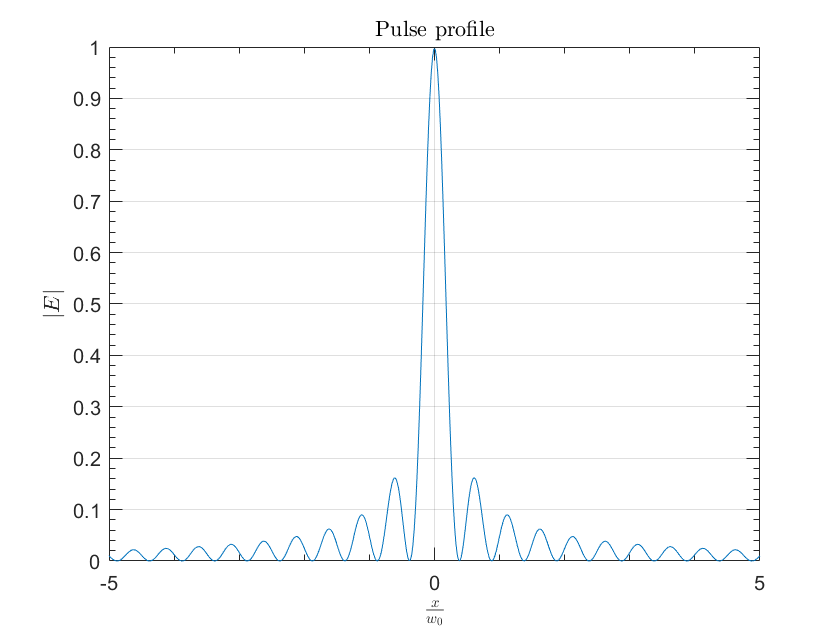

% Parameters
lambda = 1;          % Wavelength (arbitrary units)
alpha = 2*pi/lambda; % Beam parameter (α = ω/c = 2π/λ)
grid_size = 500;     % Grid size (number of points in each dimension)
L = 5;              % Spatial extent (units)
x = linspace(-L, L, grid_size); % x-axis
y = linspace(-L, L, grid_size); % y-axis
[X, Y] = meshgrid(x, y);        % 2D grid
rho = sqrt(X.^2 + Y.^2);        % Radial distance
q = 0;                          % Bessel order
% Calculate the field
E = besselj(q, alpha * rho);    % Bessel beam field (J_0)

% Intensity profile
I = abs(E).^2;                 % Intensity (proportional to J_0^2)

figure;
plot(x, I(round(grid_size/2),:))
title('Pulse profile', "Interpreter", "latex"); 
xlabel('$\frac{x}{w_0}$', "Interpreter", "latex"); 
ylabel('$|E|$', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);

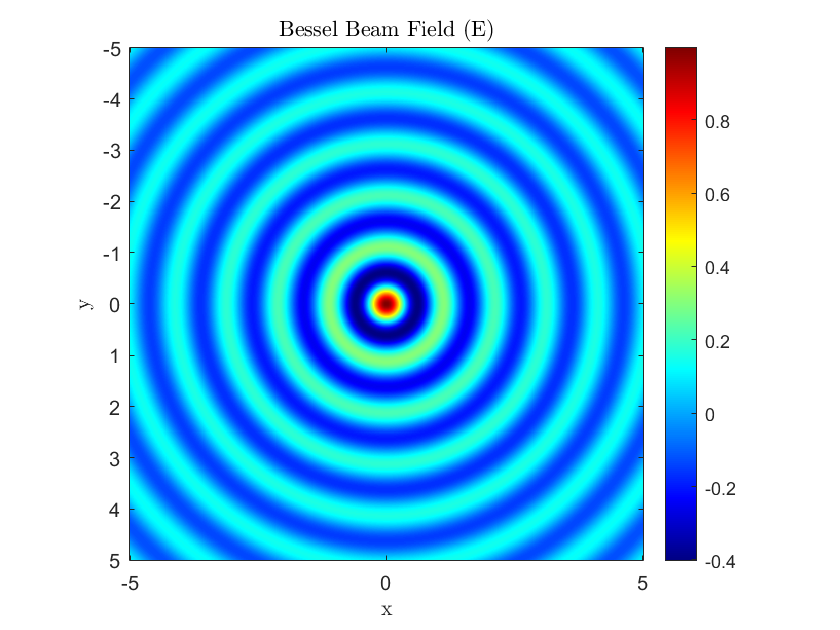


% Plotting the field and intensity
figure;
imagesc(x, y, E);
colorbar;
axis image;
title('Bessel Beam Field (E)', "Interpreter", "latex");
xlabel('x', "Interpreter", "latex");
ylabel('y', "Interpreter", "latex");
colormap jet

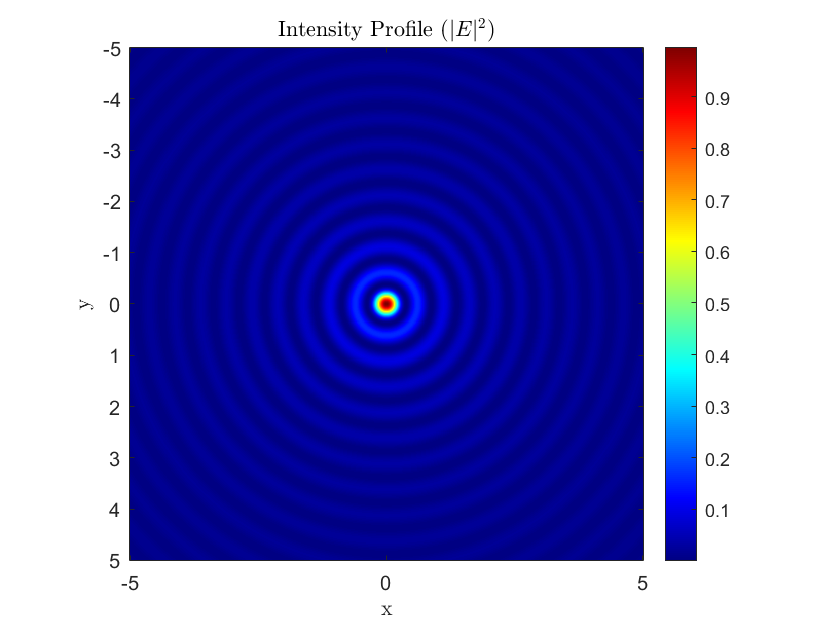


figure;
imagesc(x, y, I);
colorbar;
axis image;
title('Intensity Profile $(|E|^2)$', "Interpreter", "latex");
xlabel('x', "Interpreter", "latex");
ylabel('y', "Interpreter", "latex");
colormap jet

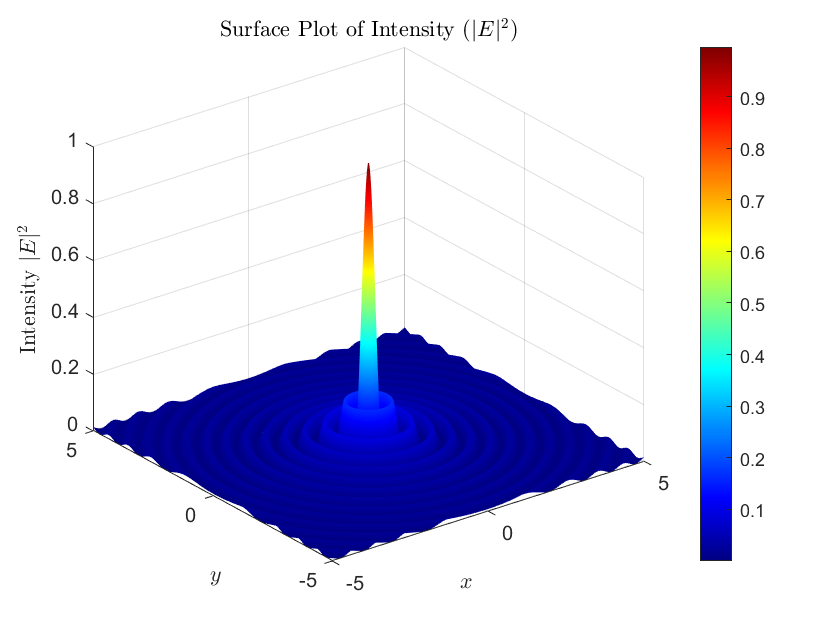



% Surface Plot of Intensity

figure;
surf(x, y, I);
shading interp
colorbar;
colormap jet;
title('Surface Plot of Intensity $(|E|^2)$', 'Interpreter', 'latex');
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('Intensity $|E|^2$', 'Interpreter', 'latex');
xlim([-L L])
ylim([-L L])
grid on;